clear
close all
clc

% load lab data
labs = readtable('20240809_labs.txt','Delimiter','|');
labs = removevars(labs,{'ID','NOTES'});

% isolate platelet counts
platelet_count_raw = labs(strcmpi(labs.ITEM_ID, 'Platelet Count'),:);
platelet_count_raw = removevars(platelet_count_raw,{'ITEM_ID'});
platelet_count_raw = sortrows(platelet_count_raw,{'SUBJECT_ID','HR'});

% trim time
platelet_count_filtered = platelet_count_raw(platelet_count_raw.HR > -24*2 & platelet_count_raw.HR < 1000,:);
platelet_count_filtered = sortrows(platelet_count_filtered,{'SUBJECT_ID','HR'});

% round measuements timestamps (average values of any duplicate rows)
period = 4; % in hours
platelet_count_rounded = platelet_count_filtered;
platelet_count_rounded.HR = round(platelet_count_filtered.HR/period)*period;
[uniqueRows,~,groupIdx] = unique(platelet_count_rounded(:,{'SUBJECT_ID','HR'}),'rows');
averageValues = accumarray(groupIdx,platelet_count_rounded.VALUE,[],@mean);
platelet_count_rounded = [uniqueRows,table(averageValues,'VariableNames',{'VALUE'})];

% load blood products data
blood_products = readtable('20240809_blood_products.txt');
blood_products = removevars(blood_products,'ID');

% isolate platelet transfuctions
platelet_trans_raw = blood_products(strcmpi(blood_products.PRODUCT_ID,'Platelets'),:);
platelet_trans_raw = removevars(platelet_trans_raw,{'PRODUCT_ID'});
platelet_trans_raw = sortrows(platelet_trans_raw,{'SUBJECT_ID','HR'});

% trim time
platelet_trans_filtered = platelet_trans_raw(platelet_trans_raw.HR > -24*2 & platelet_trans_raw.HR < 1000,:);
platelet_trans_filtered = sortrows(platelet_trans_filtered,{'SUBJECT_ID','HR'});

% round transfusion timestamps (sum values of any duplicate rows
platelet_trans_rounded = platelet_trans_filtered;
platelet_trans_rounded.HR = round(platelet_trans_filtered.HR/period)*period;
[uniqueRows,~,groupIdx] = unique(platelet_trans_rounded(:,{'SUBJECT_ID','HR'}),'rows');
sumValues = accumarray(groupIdx,platelet_trans_rounded.VALUE,[],@sum);
platelet_trans_rounded = [uniqueRows,table(sumValues,'VariableNames',{'VALUE'})];

subject_list = unique(platelet_count_raw(:,{'SUBJECT_ID'}));
subject_list_max = height(subject_list);


% initialize vectors
SubjectID = [];
Time = [];
PlateletCount = [];
PlateletTrans = [];

% populate vectors with rounded times, interpolated values, and events
for i = 1:subject_list_max
    x = platelet_count_rounded.HR(platelet_count_rounded.SUBJECT_ID == subject_list.SUBJECT_ID(i));
    y = platelet_count_rounded.VALUE(platelet_count_rounded.SUBJECT_ID == subject_list.SUBJECT_ID(i));
    xx = min(x):period:max(x);
    trans_times = platelet_trans_rounded.HR(platelet_trans_rounded.SUBJECT_ID == subject_list.SUBJECT_ID(i));


    SubjectID = [SubjectID; ones(length(xx),1)*subject_list.SUBJECT_ID(i)];
    Time = [Time; xx'];
    PlateletCount = [PlateletCount; pchip(x,y,xx)'];
    PlateletTrans = [PlateletTrans; ismember(xx,trans_times)'];
end

% populate table
ecmo_platelets = table(SubjectID,Time,PlateletCount,PlateletTrans)

ecmo_platelets = 16829×4 table
    SubjectID    Time    PlateletCount    PlateletTrans
    _________    ____    _____________    _____________

        1        -40           304              0      
        1        -36           245              0      
        1        -32        231.05              0      
        1        -28           226              0      
        1        -24           231              0      
        1        -20           201              0      
        1        -16         201.5              0      
        1        -12           202              0      
        1         -8        199.26              0      
        1         -4           192              0      
        1          0        145.31              0      
        1          4            99              0      
        1          8            94              

% export table
writetable(ecmo_platelets,'ecmo_platelets.txt');

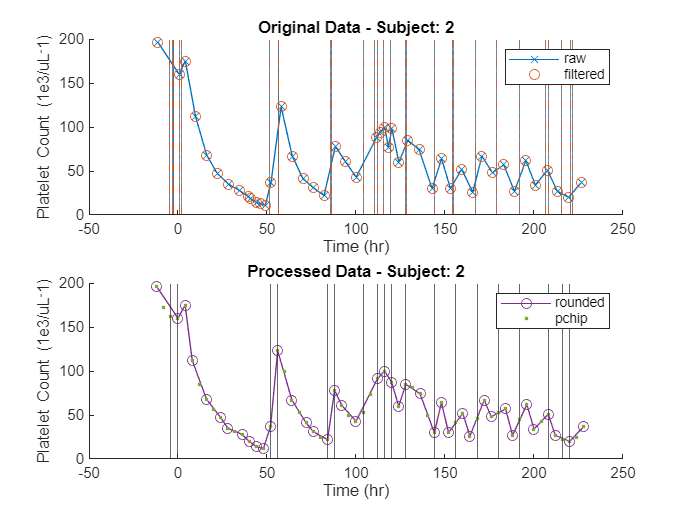

% plot data
subject = subject_list.SUBJECT_ID(2);
raw_qualifier = platelet_count_raw.SUBJECT_ID == subject;
filtered_qualifier = platelet_count_filtered.SUBJECT_ID == subject;
rounded_qualifier = platelet_count_rounded.SUBJECT_ID == subject;

close all
figure;
subplot(2,1,1) % original data

hold on

% raw data
plot(platelet_count_raw.HR(raw_qualifier),platelet_count_raw.VALUE(raw_qualifier),'x-','Color','#0072BD')
if sum(platelet_trans_raw.SUBJECT_ID == subject) > 0
    xline(platelet_trans_raw.HR(platelet_trans_raw.SUBJECT_ID == subject),'-','Color','#0072BD',HandleVisibility='off')
end

% filtered data
plot(platelet_count_filtered.HR(filtered_qualifier),platelet_count_filtered.VALUE(filtered_qualifier),'o','Color','#D95319')
if sum(platelet_trans_filtered.SUBJECT_ID == subject) > 0
    xline(platelet_trans_filtered.HR(platelet_trans_filtered.SUBJECT_ID == subject),'-.','Color','#D95319',HandleVisibility='off')
end

title('Original Data - Subject: ' + string(subject))
xlabel('Time (hr)')
ylabel('Platelet Count (1e3/uL^-1)')
legend('raw','filtered')

hold off

subplot(2,1,2) % interpolated data
x = platelet_count_rounded.HR(rounded_qualifier);
y = platelet_count_rounded.VALUE(rounded_qualifier);
xx = min(x):period:max(x);
yy = pchip(x,y,xx);

hold on

plot(x,y,'o-','Color','#7E2F8E') % rounded data
if sum(platelet_trans_rounded.SUBJECT_ID == subject) > 0
    xline(platelet_trans_rounded.HR(platelet_trans_rounded.SUBJECT_ID == subject),HandleVisibility='off')
end

plot(xx,yy,'.','Color','#77AC30') % interpolated data

title('Processed Data - Subject: ' + string(subject))
xlabel('Time (hr)')
ylabel('Platelet Count (1e3/uL^-1)')
legend('rounded','pchip')

hold off

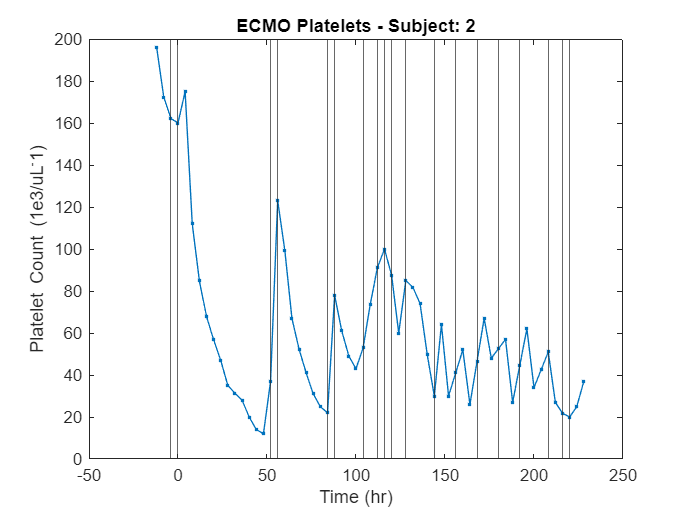


% test plot for data structure
figure;
plot(ecmo_platelets.Time(ecmo_platelets.SubjectID == subject),ecmo_platelets.PlateletCount(ecmo_platelets.SubjectID == subject),'.-');
if sum(ecmo_platelets.SubjectID == subject & ecmo_platelets.PlateletTrans == 1) > 0
    xline(ecmo_platelets.Time(ecmo_platelets.SubjectID == subject & ecmo_platelets.PlateletTrans == 1))
end
title('ECMO Platelets - Subject: ' + string(subject))
xlabel('Time (hr)')
ylabel('Platelet Count (1e3/uL^-1)')